load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\Prueba_Motor_4V % para cargar el experimento a 4 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\Prueba_Motor_4V_Negativo% para cargar el experimento a -4 V


Pruebas con el archivo de 4V

tiempo = Prueba_Motor_4V(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_4V(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_4V(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

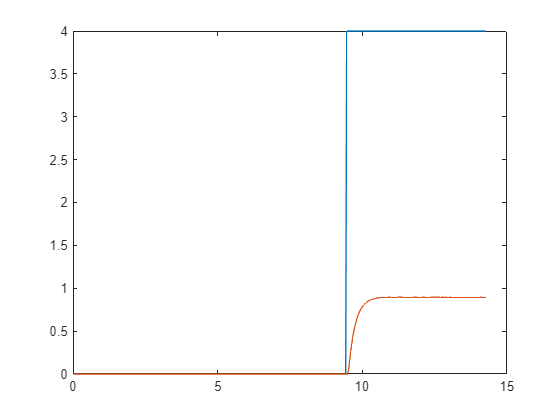

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y

Establecimiento de intervalos de interes:

%Seleccion de la parte de interes de la grafica
t_ini = tiempo(find(entrada ~= 0, 1)); % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

valor_final = mean(salida(x_fin-10: x_fin-1))

valor_final = 0.8932

ts = tiempo(find(salida >= (0.95*valor_final),1))-t_ini

ts = 0.7380

Figura con los datos de interes:

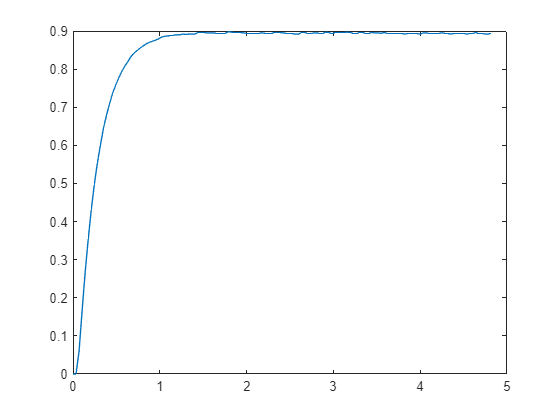

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y

________________________________________________________________________________________________________________________

Pruebas con el archivo de -4V

tiempo = Prueba_Motor_4V_Negativo(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_4V_Negativo(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_4V_Negativo(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

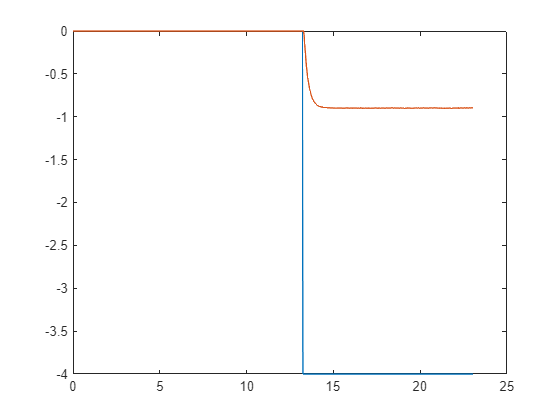

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y

Establecimiento de intervalos de interes:

%Seleccion de la parte de interes de la grafica
t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

valor_final = salida(x_fin-1) 

valor_final = -0.8960

ts=tiempo(find(salida<=(0.95*valor_final),1))-t_ini

ts = 0.7750

Figura con los datos de interes:

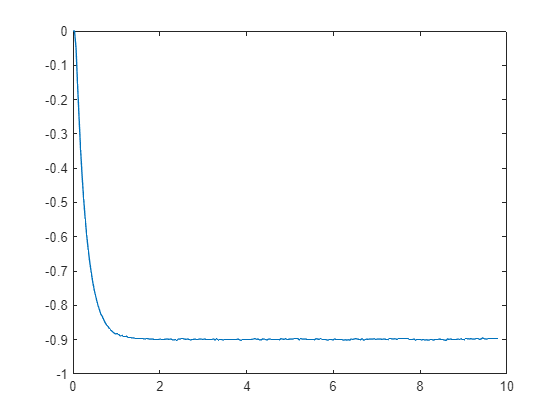

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y